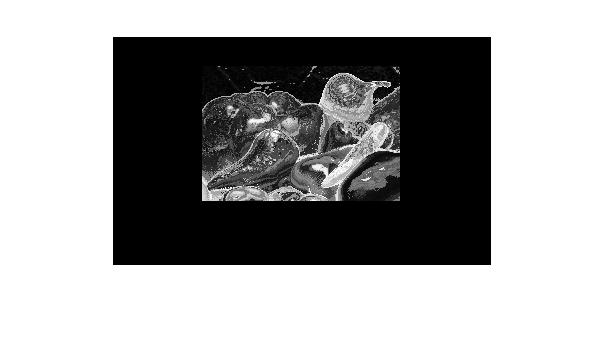

onion = imread("C:\Users\shreejaa talla\Documents\CV\Assignment 2\onion.png");
peppers = imread("C:\Users\shreejaa talla\Documents\CV\Assignment 2\peppers.png");

imshow(onion)

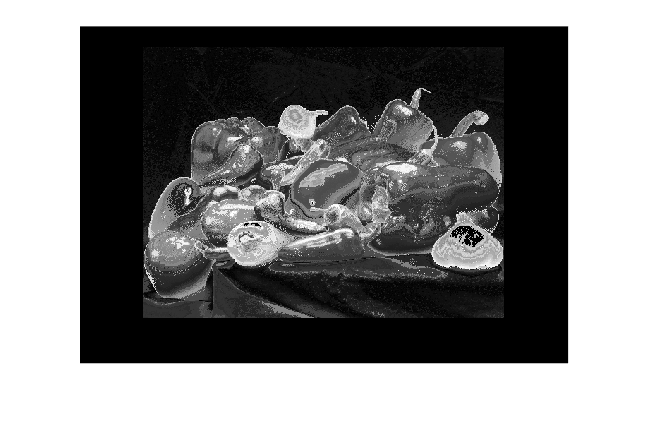

imshow(peppers)

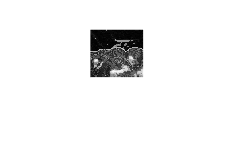

% non-interactively
rect_onion = [111 33 65 58];
rect_peppers = [163 47 143 151];
sub_onion = imcrop(onion,rect_onion);
sub_peppers = imcrop(peppers,rect_peppers);

% OR 
   
% interactively
%[sub_onion,rect_onion] = imcrop(onion); % choose the pepper below the onion
%[sub_peppers,rect_peppers] = imcrop(peppers); % choose the whole onion

% display sub images
imshow(sub_onion)

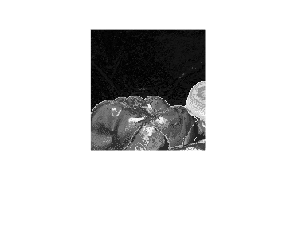

imshow(sub_peppers)

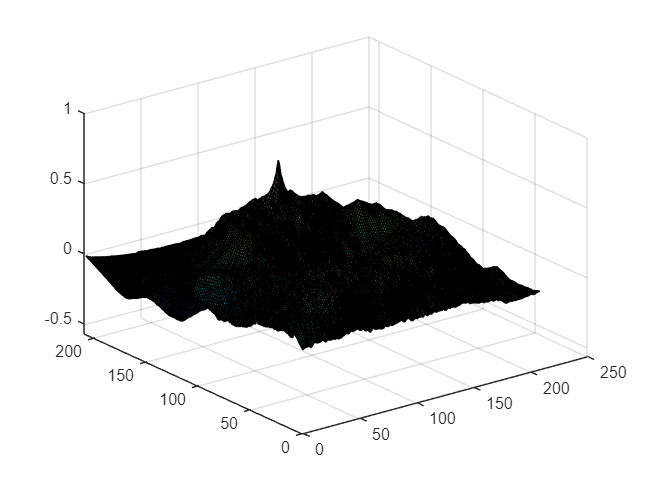

c = normxcorr2(sub_onion(:,:,1),sub_peppers(:,:,1));
figure
surf(c)

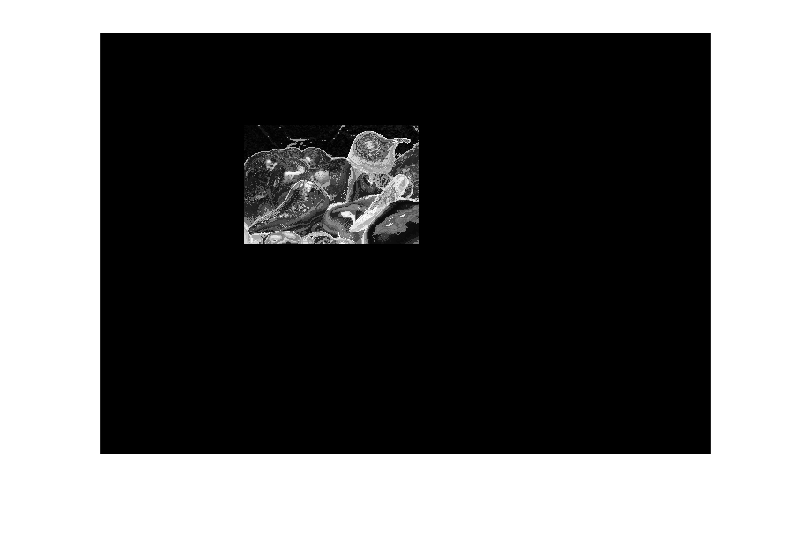

% offset found by correlation
[max_c,imax] = max(abs(c(:)));
[ypeak,xpeak] = ind2sub(size(c),imax(1));
corr_offset = [(xpeak-size(sub_onion,2)) 
               (ypeak-size(sub_onion,1))];

% relative offset of position of subimages
rect_offset = [(rect_peppers(1)-rect_onion(1)) 
               (rect_peppers(2)-rect_onion(2))];

% total offset
offset = corr_offset + rect_offset;
xoffset = offset(1);
yoffset = offset(2);
xbegin = round(xoffset + 1);
xend   = round(xoffset + size(onion,2));
ybegin = round(yoffset + 1);
yend   = round(yoffset + size(onion,1));

% extract region from peppers and compare to onion
extracted_onion = peppers(ybegin:yend,xbegin:xend,:);
if isequal(onion,extracted_onion) 
   disp("onion.png was extracted from peppers.png")
end
recovered_onion = uint8(zeros(size(peppers)));
recovered_onion(ybegin:yend,xbegin:xend,:) = onion;
imshow(recovered_onion)

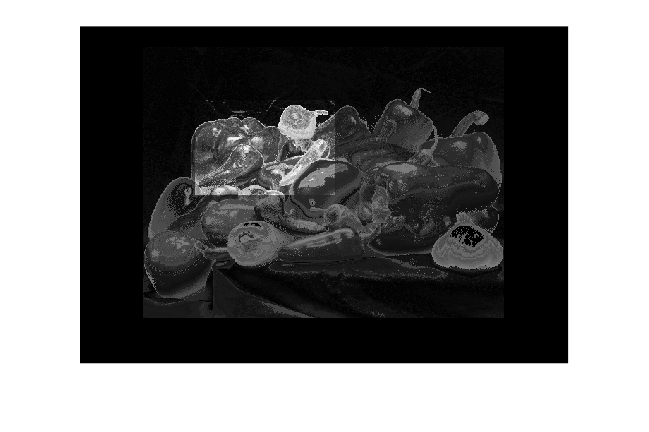

imshowpair(peppers(:,:,1),recovered_onion,"blend")